## Exercise Session 2

clear
close all

load ex2_data

[n_states,n_inputs] = size(B2);
n_inputs

n_inputs = 2

### Question 1.A

mySeed = 10;
rng(mySeed);

G = randn(n_inputs,n_states);

Notice that the values of K1 and K2 change with each iteration of the code. This is due to the fact that auxiliary matrix G is regenerated with new random numbers every time. There are thus multiple possible solutions, though the Sylvester equation is not solvable for some isolated values of G. In those cases, it is suﬃcient to choose another random matrix G (for instance by applying randn again). 

To make the values of G reproducible, set the seed of the random number generator using the function rng.

Lambda1 = blkdiag([-3 +1; -1 -3],-1);
X1 = lyap(A,-Lambda1,-B2*G);
K1 = G/X1

K1 =     2.4578   -1.1756   -1.0625
    9.4130   -3.1712    0.1374


% check
eig(A-B2*K1)

ans =   -3.0000 + 1.0000i
  -3.0000 - 1.0000i
  -1.0000 + 0.0000i


Lambda2 = blkdiag([-10 +2.5; -2.5 -10],-12.1);
X2 = lyap(A,-Lambda2,-B2*G);
K2 = G/X2

K2 =     0.0395   35.9990  -10.1983
   22.8855   14.3028   -0.6782


% check
eig(A-B2*K2)

ans =  -10.0000 + 2.5000i
 -10.0000 - 2.5000i
 -12.1000 + 0.0000i


### Question 1.B

 First, ﬁnd a state space diagram for the closed-loop system with the ﬁrst component of w as input and y, z and u as output. The other components of w and all components of v can be considered 0.

Feedback implies the relation u = $-{\mathrm{K}}_1$x for the ﬁrst controller and u = ${-\mathrm{K}}_2$x for the second. This leads to 


$$\overset{\ldotp }{x} =\left(A-B_2 K_i \right)x+B_1 \left(:,1\right)w\left(1\right)$$



$$\left\lbrack \begin{array}{c}
y\\
z\\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
C_2 \\
C_1 \\
{-D}_1 K_i \\
{-K}_i 
\end{array}\right\rbrack x+0\ldotp w\left(1\right)$$


where *i = 1, 2* indicates the first or second controller.

As you can notice, we consider as output also the control loop. This is a small trick to check how the control action evolves. If you use simulink, you don't need to put $u$ as output, but only attach the block $scope$ to the signal.

sys1 = ss(A-B2*K1,B1(:,1),[C2;C1;-D1*K1;-K1],0)

sys1 =
 
  A = 
            x1       x2       x3
   x1   -4.198    1.573  -0.3582
   x2   -1.495   -0.261   -1.181
   x3   -5.473    2.695   -2.541
 
  B = 
            u1
   x1  -0.9991
   x2   0.2875
   x3   0.2486
 
  C = 
            x1       x2       x3
   y1  -0.3362   0.8516   0.4113
   y2    1.344   0.5009   0.4826
   y3    2.313   0.1894    1.679
   y4   0.1865    1.563   -1.253
   y5   -2.458    1.176    1.062
   y6   -9.413    3.171  -0.1374
   y7   -2.458    1.176    1.062
   y8   -9.413    3.171  -0.1374
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
   y7   0
   y8   0
 
Continuous-time state-space model.



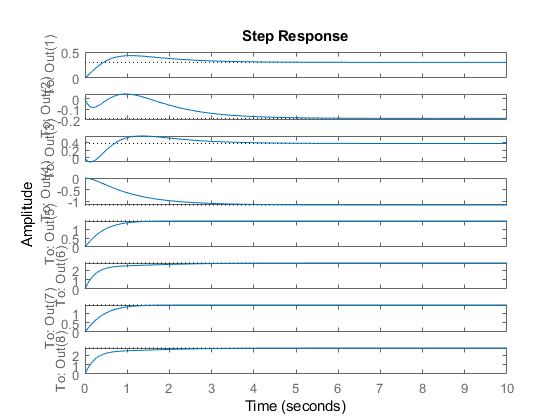

figure
step(sys1,10);

sys2 = ss(A-B2*K2,B1(:,1),[C2;C1;-D1*K2;-K2],0)

sys2 =
 
  A = 
            x1       x2       x3
   x1   -6.017   -29.92    6.462
   x2    -3.72   -6.557  -0.2608
   x3   -24.74    56.54   -19.53
 
  B = 
            u1
   x1  -0.9991
   x2   0.2875
   x3   0.2486
 
  C = 
            x1       x2       x3
   y1  -0.3362   0.8516   0.4113
   y2    1.344   0.5009   0.4826
   y3    2.313   0.1894    1.679
   y4   0.1865    1.563   -1.253
   y5  -0.0395      -36     10.2
   y6   -22.89    -14.3   0.6782
   y7  -0.0395      -36     10.2
   y8   -22.89    -14.3   0.6782
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
   y7   0
   y8   0
 
Continuous-time state-space model.



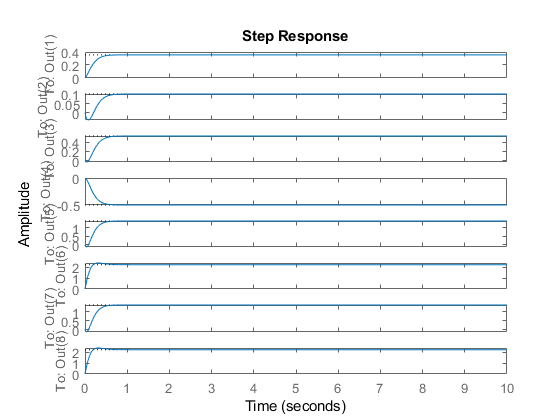

figure
step(sys2,10);

The plots clearly show that the second controller is faster than the ﬁrst one: the steady state is reached faster because the corresponding poles are further in the left half plane.

The last to plots $Out(7)$ and $Out(8)$in the step response are related to the control low $u = -Kx$.

The steady state values of the step response are given by 


$$-\left\lbrack \begin{array}{c}
C_2 \\
C_1 \\
{-D}_1 K_i \\
{-K}_i 
\end{array}\right\rbrack {\left(A{-B}_2 K_i \right)}^{-1} B_1 \left(:,\;1\right)$$


where *i = 1, 2* indicates the first or second controller. Hence, this regime value is function of the feedback gain. Pole placement only determines the poles (and hence the speed of the system) but not the transmission zeros or DC gain.

### Question 2.A

Because

$z=\left\lbrack \begin{array}{c}
C_1 x\\
D_1 u
\end{array}\right\rbrack$,

the target function becomes

$\int_0^{\infty } \left(z^T z\right)\textrm{dt}=\int_0^{\infty } \left(x^T C_1^T C_1 x+u^T D_1^T D_1 u\right)\textrm{dt}$.

Comparing this formula with page 145 in the course notes, we can find


$$\begin{array}{l}
t=0\\
T=\infty \\
Q_T =0\\
Q=C_1^T C_1 \\
R=D_1^T D_1 
\end{array}$$


The corresponding algebraic Ricatti equation can be found on page 146.

Q = C1'*C1;
R = D1'*D1;
P = are(A,B2/(R)*B2',Q);
K = R\B2'*P

K =     1.8864    0.6577   -1.4849
    1.5576   -0.0653    1.0762


The command $are$ is now deprecated. The alternative is the command $icare$. Please, check the documentation for additional information.

[~, K_, ~] = icare(A, B2, Q, R, [], [], [])

K_ =     1.8864    0.6577   -1.4849
    1.5576   -0.0653    1.0762


### Question 2.B

K_lqr = lqr(A,B2,Q,R)

K_lqr =     1.8864    0.6577   -1.4849
    1.5576   -0.0653    1.0762


### Question 2.C

Now, we can choose Q and R freely.

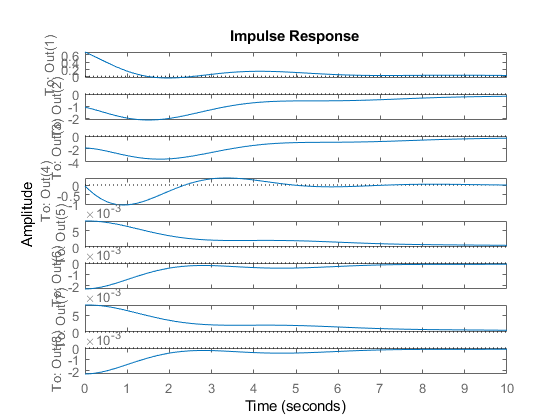

q1 = 10^(-3);
q2 = 10^(3);
Q1 = q1*eye(n_states);
Q2 = q2*eye(n_states);
R  = eye(n_inputs);
K1 = lqr(A,B2,Q1,R);
K2 = lqr(A,B2,Q2,R);
sys1 = ss(A-B2*K1,B1(:,1),[C2;C1;-D1*K1;-K1],0);
figure
impulse(sys1,10);

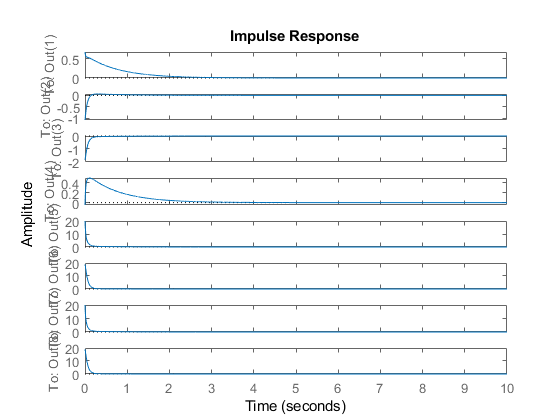

sys2 = ss(A-B2*K2,B1(:,1),[C2;C1;-D1*K2;-K2],0);
figure
impulse(sys2,10);

The outputs of *sys1* and *sys2*, respectively *y1* and *y2*, show the states *x* and the input *u* of the closed loop system for slow (*y1*) and fast (*y2*) controllers. 

Because *q1 < q2*, the states in controller 2 are more heavily weighted in the LQR criterion than those in controller 1.

One can verify this by comparing the contributions of states and inputs to the total energy under the curves $\int_0^{\infty } \left(qx^T x+u^T u\right)\textrm{dt}\;$for both controllers (or by plotting the states and inputs).

### Question 3.A

L1 = place(A',C2',eig(A-B2*K_lqr)*1.1)'

L1 =    -3.1629    2.0758
    1.2601    1.9488
    1.4921    0.1556


L2 = place(A',C2',eig(A-B2*K_lqr)*10)'

L2 =    54.5007   40.7629
  169.4058   67.8669
 -224.7487 -109.5183


To verify, we calculate and compare the eigenvalues

State observer L1

eig(A-B2*K_lqr)*1.1

ans =   -1.3105 + 0.0000i
  -3.2287 + 1.6327i
  -3.2287 - 1.6327i


eig(A-L1*C2)

ans =   -3.2287 + 1.6327i
  -3.2287 - 1.6327i
  -1.3105 + 0.0000i


State observer L2

eig(A-B2*K_lqr)*10

ans =  -11.9137 + 0.0000i
 -29.3518 +14.8426i
 -29.3518 -14.8426i


eig(A-L2*C2)

ans =  -11.9137 + 0.0000i
 -29.3518 +14.8426i
 -29.3518 -14.8426i


### Question 3.B

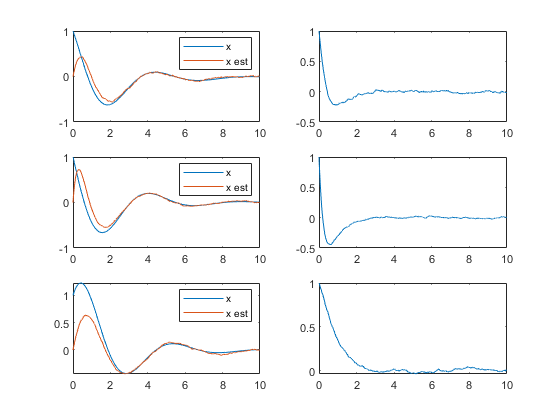

T = 999;

n_w = size(B1, 2); 
[n_v,n_states] = size(C2); 

w = 0.1*randn(n_w,T);
v = 0.1*randn(n_v,T);
x0 = ones(n_states,1); 

sys1 = ss(A-L1*C2,[B1 -L1],eye(n_states),zeros(size(A,1),size(B1,2)+size(L1,2)));
t = (0:1:(T-1))/100;
error1 = lsim(sys1,[w;v],t,x0);
sys2 = ss(A-L2*C2,[B1 -L2],eye(n_states),zeros(size(A,1),size(B1,2)+size(L2,2)));
t = (0:1:(T-1))/100;
error2 = lsim(sys2,[w;v],t,x0);

sys_x = ss(A,zeros(n_states,1),eye(n_states,n_states),zeros(n_states,1));
x = lsim(sys_x,zeros(size(t)),t,x0);

figure
for i=1:3
    subplot(3,2,2*i-1)
    plot(t,[x(:,i) x(:,i)-error1(:,i)])
    legend('x','x est')
    subplot(3,2,2*i)
    plot(t,error1(:,i));
end

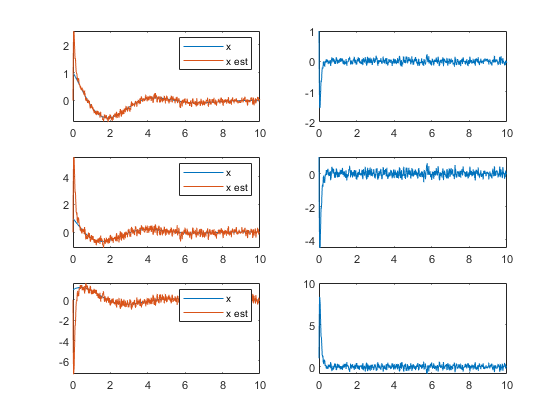

figure
for i=1:3
    subplot(3,2,2*i-1)
    plot(t,[x(:,i) x(:,i)-error2(:,i)])
    legend('x','x est')
    subplot(3,2,2*i)
    plot(t,error2(:,i));
end

 Conclusion: L2 is faster, but more sensitive to (measurement) noise.

### Question 4.A

 The covariance matrices of process and measurement noise are unit matrices (given) so that Q = R = I.

n_w = size(B1,2);
n_v = size(C2,1);
L = lqe(A,B1,C2,eye(n_w),eye(n_v))

L =    -0.1495    1.7387
    0.3433    1.0083
    0.4288   -0.2339


### Question 4.B

Let's define L1 and L2 such that

L1: Q > R

L2: Q < R

Q = 1;
R = 0.1;
L1 = lqe(A,B1,C2,Q*eye(n_w),R*eye(n_v))

L1 =    -0.8440    4.8992
    1.9768    3.2248
    1.7842   -0.9296


Q = 0.1;
R = 1;
L2 = lqe(A,B1,C2,Q*eye(n_w),R*eye(n_v))

L2 =     0.0049    0.5127
    0.0537    0.2598
    0.0600    0.0330


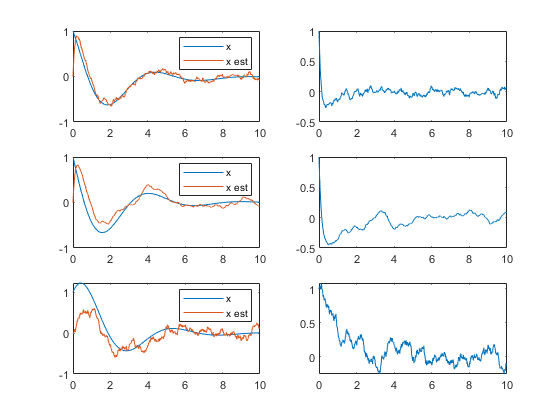

T = 999;
w = 1*randn(size(B1,2),T);
v = 0.1*randn(size(L1,2),T);
sys1 = ss(A-L1*C2,[B1 -L1],eye(size(A)),zeros(size(A,1),size(B1,2)+size(L1,2)));
t = (0:1:(T-1))/100;
error1 = lsim(sys1,[w;v],t,x0);

sys2 = ss(A-L2*C2,[B1 -L2],eye(size(A)),zeros(size(A,1),size(B1,2)+size(L2,2)));
t = (0:1:(T-1))/100;
error2 = lsim(sys2,[w;v],t,x0);

sys_x = ss(A,zeros(n_states,1),eye(n_states,n_states),zeros(n_states,1));
x = lsim(sys_x,zeros(size(t)),t,x0);

figure
for i=1:3
    subplot(3,2,2*i-1)
    plot(t,[x(:,i) x(:,i)-error1(:,i)])
    legend('x','x est')
    subplot(3,2,2*i)
    plot(t,error1(:,i));
end

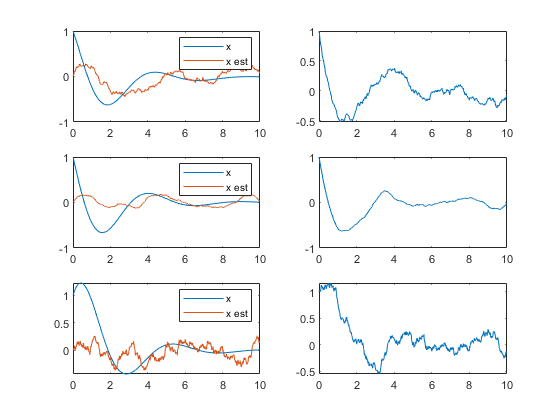

figure
for i=1:3
    subplot(3,2,2*i-1)
    plot(t,[x(:,i) x(:,i)-error2(:,i)])
    legend('x','x est')
    subplot(3,2,2*i)
    plot(t,error2(:,i));
end

We can conclude that the ﬁrst Kalman ﬁlter makes a better tradeoﬀ between noise and speed.

### Question 5.A

The following equations hold (see page 193-194):


$$\begin{array}{l}
\overset{\ldotp }{x} =\textrm{Ax}+B_2 u+B_1 w\\
y=C_2 x+v\\
z=\left\lbrack \begin{array}{c}
C_1 x\\
D_1 u
\end{array}\right\rbrack \;\\
\overset{\ldotp }{\hat{x} } =A\hat{x} +B_2 u+L\left(y-C_2 \hat{x} \right)\\
u=-K\hat{x} 
\end{array}$$


or put together


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x} \\
\overset{\ldotp }{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A-B_2 K & B_2 K\\
0 & A-LC_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
B_1  & 0\\
B_1  & -L
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w\\
v
\end{array}\right\rbrack ,\\
z=\left\lbrack \begin{array}{cc}
C_1  & 0\\
-D_1 K & D_1 K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{x} \\
\overset{\ldotp }{\hat{x} } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w\\
v
\end{array}\right\rbrack \ldotp 
\end{array}$$


### Question 5.B

When you introduce the estimation error $\tilde{x} =x-\hat{x}$ in the equations instead of $\hat{x}$, you obtain:


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\tilde{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A-B_2 K & B_2 K\\
0 & A-LC_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\tilde{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
B_1  & 0\\
B_1  & -L
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w\\
v
\end{array}\right\rbrack ,\\
z=\left\lbrack \begin{array}{cc}
C_1  & 0\\
-D_1 K & D_1 K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\tilde{x} } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w\\
v
\end{array}\right\rbrack \ldotp 
\end{array}$$


This illustrates that the poles of the combined system (plant + compensator) are given by the union of the poles of the estimator and the controller: 

union(eig(A-B2*K), eig(A-L*C2))

ans =   -1.1914 + 0.0000i
  -1.6173 + 0.0000i
  -1.4036 - 1.1928i
  -1.4036 + 1.1928i
  -2.9352 - 1.4843i
  -2.9352 + 1.4843i


This is called the separation principle. Note that this guarantees that the closed loop system is stable (as expected) but the compensator itself may still be unstable. Stability of controllers and compensators may be important. In general, the possibility of designing stable stabilizing controllers depends on poles and zeros of the plant in a nontrivial way (as illustrated, for example, by the Parity Interlacing Property on page 85).